# Figure 8: fMRI data and model fit from the second experiment

## Description.....

## load data and model files

whichData = 'fmri2'; 
dataLoc      = fullfile(temporalfMRIRootPath, 'files');

[a, b]    = loadfiles(dataLoc, whichData);

% average data
data   = squeeze(mean(a.(whichData).data)); % n Rois x n bootstraps x n temporal conditions
RoiNms = a.(whichData).nm;

% extract model
lin = b.(whichData).lin;
stn = b.(whichData).stn;

## compute mean and std for both the data and the model fit

order  = [25, 1 : 6, 5, 7 : 12, 25, 13 : 18, 17, 19 : 24];
nBoots = 100;

mdata = []; sdata = []; mlin = []; slin = []; mstn = []; sstn = [];

% prep for averaging the summary statistics
metric = [stn.derivedParam.r_double; stn.derivedParam.t_isi];

for k = 1 : length(RoiNms)
   % mean and std for data
   mdata(k, :) = squeeze(mean(data(k, :, :), 2));
   sdata(k, :) = squeeze(std(data(k, :, :), [], 2));
   
   idx = (k - 1) * nBoots +1 : k * nBoots;
   
   % mean and std for the linear model fit
   mlin(k, :) = mean(lin.prd(idx, :));
   slin(k, :) = std(lin.prd(idx, :));
   
   % mean and std for the stn model git
   mstn(k, :) = mean(stn.prd(idx, :));
   sstn(k, :) = std(stn.prd(idx, :));
   
   % median and center 50% for the summary statistics
   mmetric(k, :) = median(metric(:, idx), 2);
   smetric(k, :, :) = prctile(metric(:, idx), [25, 75], 2);
end

## plot figure 8

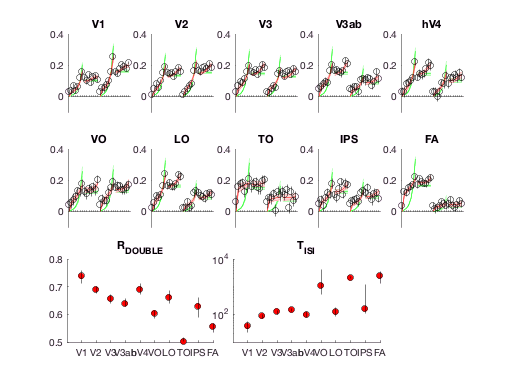

figure (8), clf
counts = [1 : 7; 8 : 14; 15 : 21; 22 : 28];

for k = 1 : 10
    subplot(3, 5, k),
    % plot model fits
    for k1 = 1 : 4
        shadedErrorBar(counts(k1, :), mlin(k, order(counts(k1, :))), slin(k, order(counts(k1, :))), 'g-'), hold on
        shadedErrorBar(counts(k1, :), mstn(k, order(counts(k1, :))), sstn(k, order(counts(k1, :))), 'r-')
    end
    % plot data
    plot(mdata(k, order), 'ko'), 
    for k1 = 1: length(order)
       plot([k1, k1], [mdata(k, order(k1))-sdata(k, order(k1)),mdata(k, order(k1))+sdata(k, order(k1))], 'k-') 
    end 
    xlim([0.5, length(order) + 0.5]), ylim([-0.1, 0.4]), set(gca, 'xaxislocation', 'origin'), box off
    set(gca, 'xtick', 1 : length(order), 'xticklabel', []), title(RoiNms{k})
end

% plot summary metrics
subplot_init = [11, 13]; y_range = [0.5, 0.8; 10, 10^4]; title_txt = {'R_{DOUBLE}', 'T_{ISI}'};
for k = 1 : 2
    subplot(3, 5, subplot_init(k) : subplot_init(k) + 1)
    if k == 1
        plot(mmetric(:, k), 'ko', 'markerfacecolor', 'r'), hold on
        for k1 = 1 : length(RoiNms)
            plot([k1, k1], squeeze(smetric(k1, k, :)), 'k-')
        end
    elseif k == 2
        semilogy(mmetric(:, k), 'ko', 'markerfacecolor', 'r'), hold on
        for k1 = 1 : length(RoiNms)
            semilogy([k1, k1], squeeze(smetric(k1, k, :)), 'k-')
        end
    end
    box off, set(gca, 'xtick', 1 : length(RoiNms), 'xticklabel', RoiNms), ylim([y_range(k, :)]), title(title_txt{k})
end